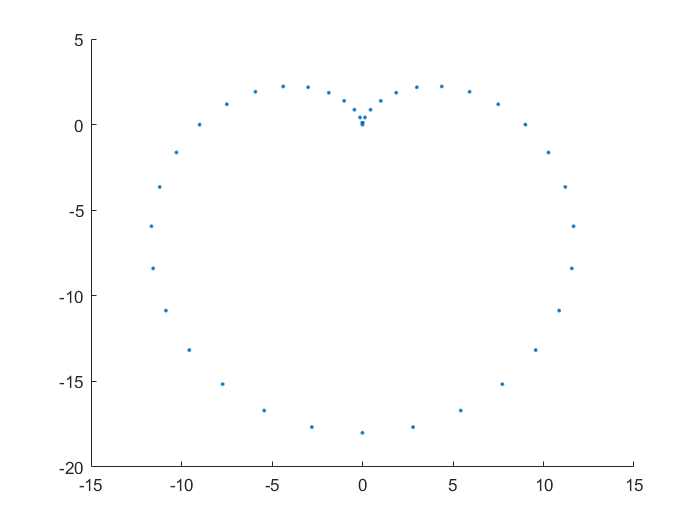

clear;
clf;
% 圆形数据生成
% count = 20;
% theta = 0:(2*pi/count):2*pi;
% Points = [cos(theta'),sin(theta')];
% Normals = Points;
% scatter(Points(:,1),Points(:,2),'.');
% n = length(theta);

% 心形数据生成
count = 40;
a = 9;
theta = 0:(2*pi/count):2*pi;
X = a*cos(theta')-cos(2*theta')*a/2-a/2;
Y = a*sin(theta')-sin(2*theta')*a/2;
Points = [Y,X];
Xn = 2.*X+a-a.*X./sqrt(X.^2+Y.^2);
Yn = 2*Y-a.*Y./sqrt(X.^2+Y.^2);
Normals = [Yn,Xn];
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

% 超椭圆数据生成
% count = 20;
% a = 1;
% b = 1;
% m = 1.1;
% theta = 0:(pi/2/count):pi/2;
% len = length(theta);
% Points = [a*cos(theta').^(2/m), b*sin(theta').^(2/m)];
% 
% hold on;
% Gradient = [m/a*Points(:,1).^(m-1),m/b*Points(:,2).^(m-1)];
% Gradient(1,:) = Points(1,:);
% Gradient(21,:) = Points(21,:);
% GradientLen = sqrt(Gradient(:,1).^2+Gradient(:,2).^2);
% 
% Gradient = [Gradient(:,1)./GradientLen, Gradient(:,2)./GradientLen,];
% Points = [Points(:,1),Points(:,2);-Points(1:20,1),Points(1:20,2)];
% Points = [Points(:,1),Points(:,2);Points(2:40,1),-Points(2:40,2)];
% Gradient = [Gradient(:,1),Gradient(:,2);-Gradient(1:20,1),Gradient(1:20,2)];
% Gradient = [Gradient(:,1),Gradient(:,2);Gradient(2:40,1),-Gradient(2:40,2)];
% Normals = Gradient;
% 
% scatter(Points(:,1),Points(:,2),'.');
% for i=1:4*len-4
% plot([Points(i,1),Points(i,1)+Gradient(i,1)],[Points(i,2),Points(i,2)+Gradient(i,2)])
% end
% hold off;
% n = 4*length(theta)-4;

%Cassini Oval
% count1 = 40;
% count2 = 2;
% a = 1;b = sqrt(1.001);
% theta = [0         :(pi/2/count1): pi/2-0.71,...
%         pi/2-0.7   :(pi/2/count2): pi/2+0.7,...
%         pi/2+0.71  :(pi/2/count1): 3*pi/2-0.71,...
%         3*pi/2-0.7 :(pi/2/count2): 3*pi/2+0.7,...
%         3*pi/2+0.71:(pi/2/count1): 2*pi-0.01];
% M = 2*a^2.*cos(2*theta)+2*sqrt(a^4.*(cos(2.*theta)).^2-a^4+b^4); 
% Points = sqrt(M./2)'.*[cos(theta'),sin(theta')];
% 
% dM = -4*a^2.*sin(2*theta) - 4*(a^4).*sin(2.*theta).*cos(2*theta).*(b^4-a^4+a^4*(cos(2.*theta)).^2).^(-0.5);
% dx = 0.25.*dM.*cos(theta).*(M./2).^(-0.5) - sqrt(M./2).*sin(theta);
% dy = 0.25.*dM.*sin(theta).*(M./2).^(-0.5) + sqrt(M./2).*cos(theta);
% dx = dx./sqrt(dx.^2+dy.^2);
% dy = dy./sqrt(dx.^2+dy.^2);
% Normals = [dy',-dx'];

% hold on;
% for i=1:length(theta)
% plot([Points(i,1),Points(i,1)+Normals(i,1)],[Points(i,2),Points(i,2)+Normals(i,2)])
% scatter(Points(:,1),Points(:,2),'.');
% end
% hold off;

n = length(theta);

% 数据生成
% count = 60;
% theta = 0:(4*pi/count):4*pi;
% Points = [theta'.*cos(2*theta'),theta'.*sin(theta')];
% dx = cos(2.*theta)-2.*theta.*sin(2*theta);
% dy = sin(theta)+theta.*cos(theta);
% dx = dx./sqrt(dx.^2+dy.^2);
% dy = dy./sqrt(dx.^2+dy.^2);
% Normals = [dy',-dx'];
% hold on;
% for i=1:length(theta)
% plot([Points(i,1),Points(i,1)+Normals(i,1)],[Points(i,2),Points(i,2)+Normals(i,2)])
% scatter(Points(:,1),Points(:,2),'.');
% end
% hold off;
% n = length(theta);

k = 5*ones(n,1);
% k(5:9)=4*ones(5,1);
% k(11:13)=4*ones(3,1);
s = -1.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
% 计算各点支撑半径
SupportSizes = zeros(n,1);
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
% 设置拟合系数
ApproxArgs = 0.5*ones(n,1);
%  ApproxArgs(15:40,1) = 3*ones(26,1);
%  ApproxArgs(75:100,1) = 3*ones(26,1);
% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7
            valsum = C(indices(j))+H(j);
            rbfsum = 1;
            break;
        end
        value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
        %value = rbf_wend(dists(j)/SupportSizes(indices(j)));        
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
% f = @(x,y)(CalRBFV(x,y,k,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C));
% area = [-1.2,1.2,-1.2,1.2];
% fp = fimplicit(f, area);
% hold on;
% scatter(Points(:,1),Points(:,2),'.');
% hold off;
% result = [(fp.XData)',(fp.YData)'];

% 画隐曲线
f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
% area = [-1.5,1.5,-0.7,0.7];
area = [-12,12,-19,3];
fp = fimplicit(f, area);

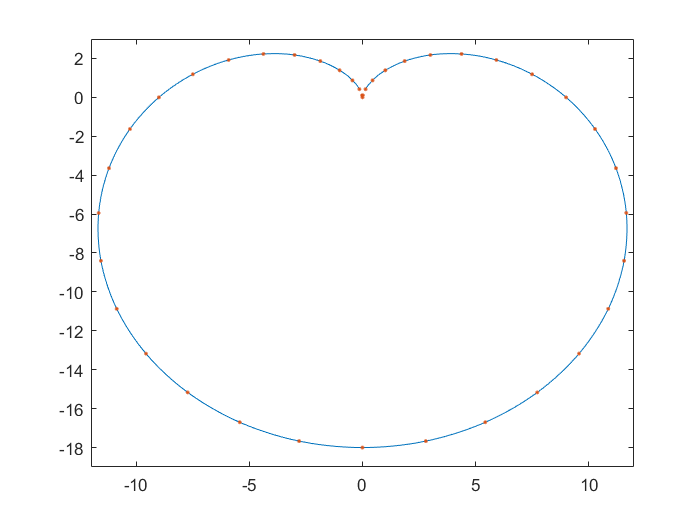

% x=-1:0.1:1;
% y=-1:0.1:1;
% [MX,MY]=meshgrid(x,y);
% MZ=zeros(size(MX));
% for i=1:size(MX,1)
%     for j=1:size(MX,2)
%         MZ(i,j)=f(MX(i,j),MY(i,j));
%     end
% end
% surf(x,y,MZ)

hold on;

scatter(Points(:,1),Points(:,2),'.');
hold off;

% result = [(fp.XData)',(fp.YData)'];

% 计算误差（基于隐函数）
% f = @(x,y)(x.^2+y.^2-1);
% area = [-1.2,1.2,-1.2,1.2];
% res = 1000;
% fp = fimplicit(f, area, 'MeshDensity', res);
% realValue = [(fp.XData)',(fp.YData)'];
% kdtree = KDTreeSearcher(realValue);
% error = zeros(size(result,1),1);
% for i=1:size(result,1)
%     [indice,error(i)]=knnsearch(kdtree, result(i,:), 'K', 1);
% end
% max(error)

% % 计算误差（基于参数式）
% res = 10000;
% theta = 0:(2*pi/res):2*pi;
% realValue = [cos(theta)',sin(theta)'];
% kdtree = KDTreeSearcher(realValue);
% error = zeros(size(result,1),1);
% for i=1:size(result,1)
%     [indice,error(i)]=knnsearch(kdtree, result(i,:), 'K', 1);
% end
% max(error)

% 计算误差（基于参数式）
% res = 10000;
% theta = 0:(2*pi/res):2*pi;
% realValue = [X,Y];
% kdtree = KDTreeSearcher(realValue);
% error = zeros(size(result,1),1);
% for i=1:size(result,1)
%     [indice,error(i)]=knnsearch(kdtree, result(i,:), 'K', 1);
% end
% max(error)

